% load in gombertz growth data
T = readtable('gombertz_growth_data_1000_points.csv');
days_pred = table2array(T(1,:));
gombertz = table2array(T(2,:));
logistic = table2array(T(3,:));

% load in population change data 1st Jan Weaning
T0101 = readtable('Weaned1janPopChange.csv', 'VariableNamingRule',"preserve");
date_of_change0101 = table2array(T0101(:,1));
days_axis0101 = datetime(date_of_change0101)

days_axis0101 = 15×1 datetime array
   02/12/2019
   03/12/2019
   04/12/2019
   05/12/2019
   06/12/2019
   07/12/2019
   08/12/2019
   05/05/2020
   14/05/2020
   21/05/2020
   26/05/2020
   29/05/2020
   03/06/2020
   05/06/2020
   08/06/2020


pop_change0101 = cumsum(table2array(T0101(:,2))); %takes total sum of all prev terms

% load in population change data 5th Feb Weaning
T0502 = readtable('Weaned5febPopChange.csv', 'VariableNamingRule',"preserve");
date_of_change0502 = table2array(T0502(:,1));
days_axis0502 = datetime(date_of_change0502)

days_axis0502 = 39×1 datetime array
   28/12/2019
   29/12/2019
   30/12/2019
   31/12/2019
   01/01/2020
   02/01/2020
   03/01/2020
   04/01/2020
   05/01/2020
   06/01/2020
   07/01/2020
   08/01/2020
   09/01/2020
   10/01/2020
   11/01/2020
   28/05/2020
   03/06/2020
   10/06/2020
   10/06/2020
   12/06/2020
   18/06/2020
   18/06/2020
   19/06/2020
   22/06/2020
   23/06/2020
   24/06/2020
   25/06/2020
   29/06/2020
   29/06/2020
   30/06/2020


pop_change0502 = cumsum(table2array(T0502(:,2))); %takes total sum of all prev terms

% set up x axis in days
% start_date = datetime(2019,12,1);
% end_date = datetime(2020,6,15);
% days_axis = start_date:end_date;

% optimal weight is live weight (taken from average weight)
target_weight = 120

target_w = 105

growth_rate = 
for i = 1:length(date_of_change0101)
    pred_days = inverse_gombertz_matlab(target_weight, growth_rate)
end

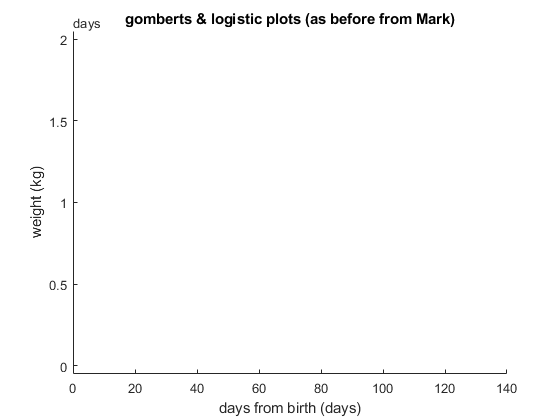

% plot weight against time
hold on
plot(gombertz, days);
plot(logistic, days);
title('gomberts & logistic plots (as before from Mark)')
xlabel('days from birth (days)')
ylabel('weight (kg)')

% load in population change in time
% plot days against weight, days against population

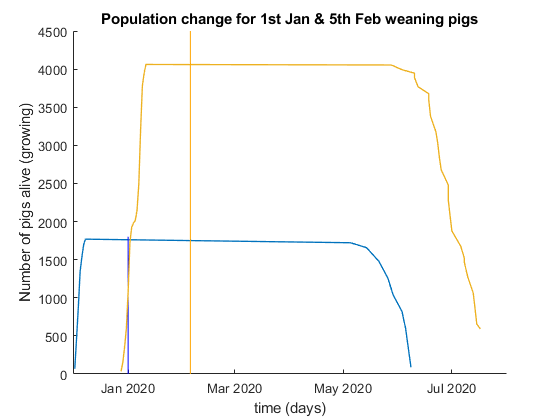

% plot population against time
clf
hold on
plot(days_axis0101, pop_change0101, 'LineWidth', 1)
plot([datetime(2020,1,1) datetime(2020,1,1)], ylim, "Color",'blue');
plot(days_axis0502, pop_change0502, "LineWidth", 1)
plot([datetime(2020,2,5) datetime(2020,2,5)], ylim, "Color",'#FFA500');
title('Population change for 1st Jan & 5th Feb weaning pigs')
xlabel('time (days)')
ylabel('Number of pigs alive (growing)')